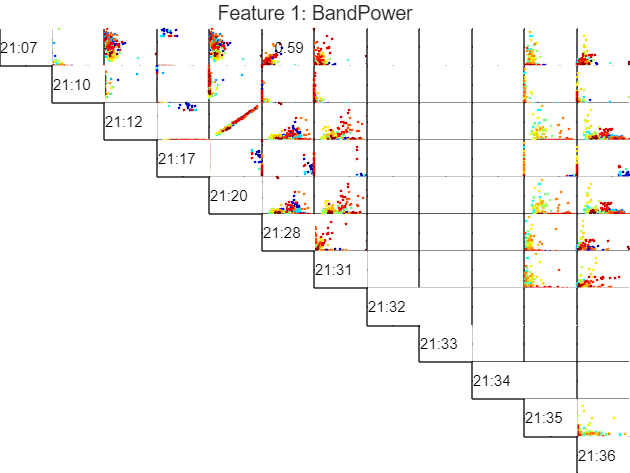

Features = DFD_FeatureTable_FreqDomain;
FeatureNames = featureNames_Freq;
SignalNames = signalNames_Freq;
lowerR2 = 0.2;
upperR2 = 0.8;  
selectedFeature = 1;
R2 = fnPlotSignalVsSignal(Features, lowerR2, upperR2, selectedFeature, FeatureNames, SignalNames, sensorNames); 

disp(num2str(R2, '%.2f  '));

0.00  0.00  0.06  0.04  0.08  0.59  0.03   NaN   NaN   NaN  0.00  0.02
0.00  0.00  0.00  0.00  0.00  0.01  0.00   NaN   NaN   NaN  0.00  0.00
0.00  0.00  0.00  0.01  0.99  0.00  0.00   NaN   NaN   NaN  0.13  0.10
0.00  0.00  0.00  0.00  0.01  0.10  0.00   NaN   NaN   NaN  0.03  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN   NaN  0.13  0.10
0.00  0.00  0.00  0.00  0.00  0.00  0.05   NaN   NaN   NaN  0.00  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN   NaN  0.00  0.17
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00


selectedSignal = 1; % row number
selectedFeature = selectedFeature + 13;
FeatureNames = FeatureNames_Combined;
[selectedSignalArray, selectedSignalData, numOfSelectedSignals] = fnSelectSignals(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2);
disp(selectedSignalArray);

     1     6



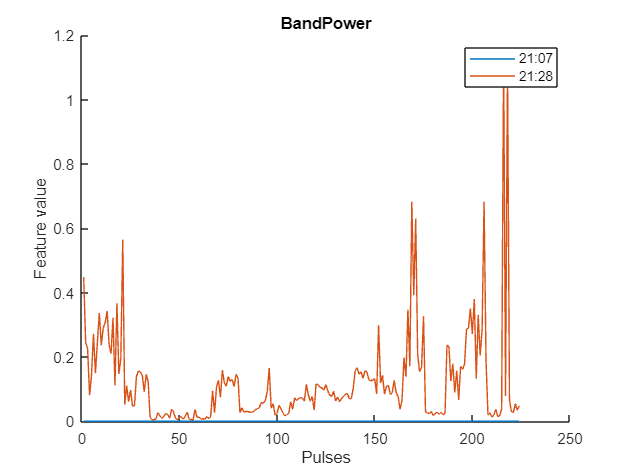

figure(); hold on;
leg = {numOfSelectedSignals};
for i = 1:numOfSelectedSignals
    plot(selectedSignalData{i});
    txtTemp = char(sensorNames(selectedSignalArray(i)));
    leg{i} = char(txtTemp(1:5));
end
title(FeatureNames(selectedFeature));
xlabel("Pulses");
ylabel("Feature value");
legend(leg);

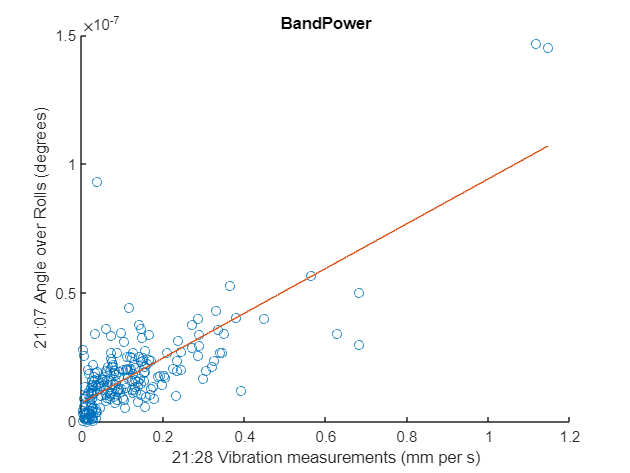

FIT = 36.31

for index1 = 1 : numOfSelectedSignals
    for index2 = index1 + 1 : numOfSelectedSignals
        fnPlotModel(selectedSignalData{index1}, selectedSignalData{index2}, FeatureNames(selectedFeature), sensorNames(selectedSignal), sensorNames(selectedSignalArray(index)));
    end
end